## v0 Intro

In this scrip i try to process experiment data, delete z, and make an average between x and y data, save as new processed_data.

## v3 Intro

In this scrip i try to mix 5s data with 30s processed_data. The out put data is the relationship between t and MSD.

## Loading data

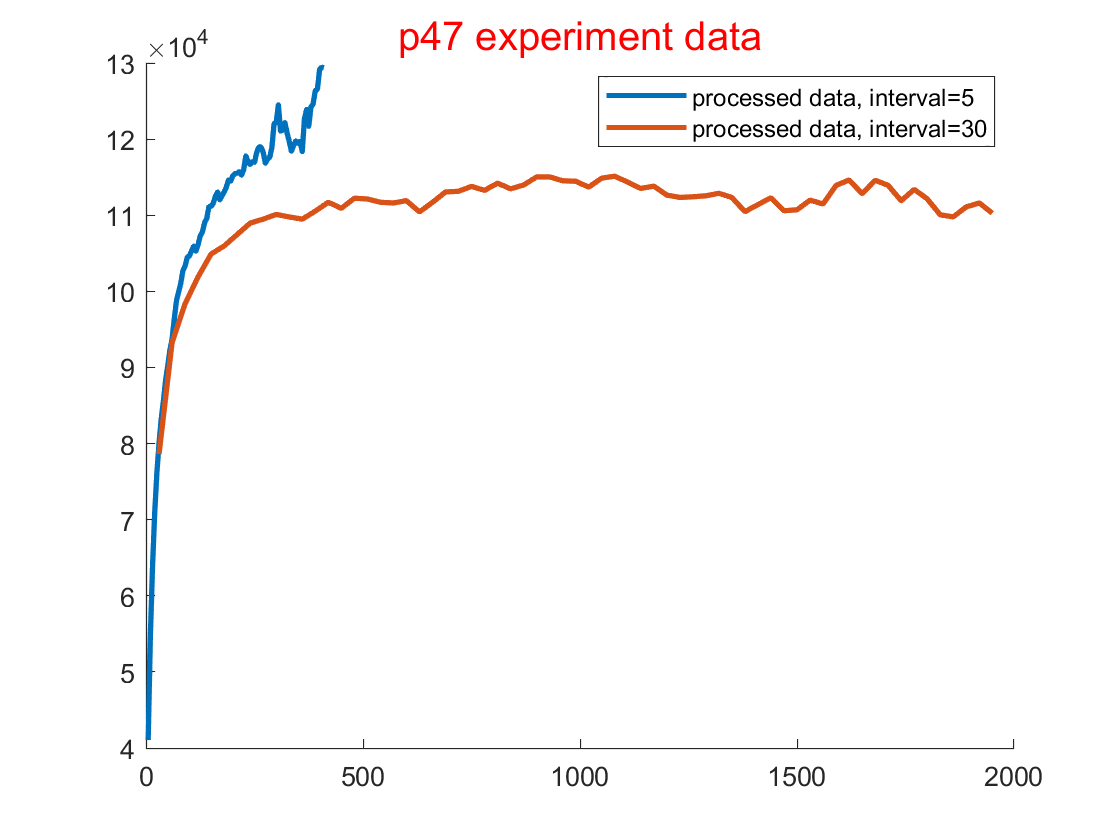

data_name='p47';
experiment_interval_list=[5,30];
figure
hold on
for i=1:length(experiment_interval_list)
    experiment_interval=experiment_interval_list(i);
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',data_name,'_',num2str(experiment_interval),'s.mat'],'processed_MSD','reserved_length')
    load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_',num2str(experiment_interval),'s_All.mat'])
    %reserved_length=reserved_length_list(i);
    %plot(experiment_interval*(1:length(eval(['MSD_',data_name,'_',num2str(experiment_interval),'s_All']).MSD_PP)),eval(['MSD_',data_name,'_',num2str(experiment_interval),'s_All']).MSD_PP,'LineWidth',2)
    plot(experiment_interval*(1:reserved_length),processed_MSD(1:reserved_length),'LineWidth',2,"DisplayName",['processed data, interval=',num2str(experiment_interval)]);
    t_scale=experiment_interval*(1:reserved_length);
    if i==1
        t_MSD1=[t_scale;processed_MSD(1:reserved_length)'];
    else
        t_MSD2=[t_scale;processed_MSD(1:reserved_length)'];
    end
end
legend('Location',"best");
%title(['p47\_5s experiment data'],'Fontsize',15,"Color",'r');
title([data_name,' experiment data'],'Fontsize',15,"Color",'r');

## Selecting before mixing

Selecting_Mode='Discard'; %'discard','average'

discard mode: discard data in t_MSD1 if it differ 10% from data in t_MSD2

allowed_relative_error=0.05;
if Selecting_Mode=='Discard'
    for t=experiment_interval_list(2)*(3:floor(length(t_MSD1(1,:))*experiment_interval_list(1)/experiment_interval_list(2)))
        data1=t_MSD1(2,t/experiment_interval_list(1));
        data2=t_MSD2(2,t/experiment_interval_list(2));
        if data1>data2*(1+allowed_relative_error)
            break
        elseif data1<data2*(1-allowed_relative_error)
            break
        end
    end
    t_MSDnew1=t_MSD1(:,1:t/experiment_interval_list(1));

average mode: for t_scale public area, mix data is the average of MSD1 & 2.

elseif Selecting_Mode=='Average'
    t_mixMSD=[];
end

show result

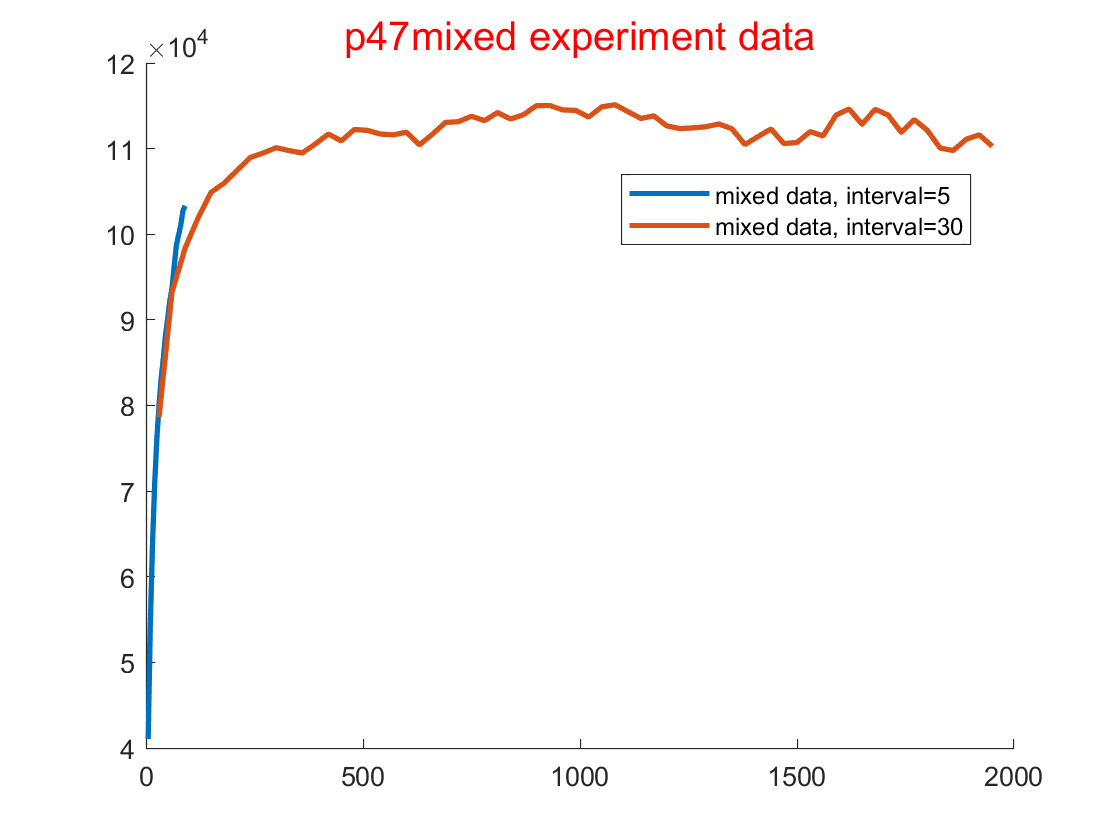

figure
hold on
plot(t_MSDnew1(1,:),t_MSDnew1(2,:),'LineWidth',2,"DisplayName",['mixed data, interval=',num2str(experiment_interval_list(1))]);

plot(t_MSD2(1,:),t_MSD2(2,:),'LineWidth',2,"DisplayName",['mixed data, interval=',num2str(experiment_interval_list(2))]);
title([data_name,'mixed experiment data'],'Fontsize',15,"Color",'r');
legend("Location","best")

## Mixing data

t_mixMSD=[t_MSD2,t_MSDnew1];

## Mixing curve

## Saving part

saving_location='C:\Users\zhouquan\OneDrive\research\polychrom simulation\newProcessedData';
%save([saving_location,'\mixed data ',data_name,' ',num2str(allowed_relative_error),'Difference',Selecting_Mode,'.mat'],'t_mixMSD','data_name','allowed_relative_error')